# Lab 2: Forward Kinematics

In this part of the lab, we're going to find the workspace of a two-link, planar arm using forward kinematics. The goal here is to determine what area the robot can reach given the physical constraints of its joints and link lengths. The model that we'll be working with is meant to approximate a robot which you'll be working with in later hardware labs.

First, we need to define the lengths of the robot's two links in meters:

L1 = 0.1524; % The length of the first link
L2 = 0.1524; % The length of the second link

**Question:*** The lengths of the robot's links will obviously constrain the outer edge robot's workspace, since it would be impossible for it to reach further than the length of both links combined in any one direction. But can the lengths of a robot's links also limit the lower limit of its workspace? i.e. do certain link lengths prevent the robot from reaching all the way back to its base?*

In addition to the link lengths, real joints often have a maximum range of angular motion. Let's define the acceptable angles for our robot's joints below. Note that our kinematic equations take the angle as radians, but our specifications for the 2.12 robot are in degrees. We can convert between the two using the deg2rad() function.

q1_upper = deg2rad(113.7); % 113.7 degree for 2.12 robot
q1_lower = deg2rad(-113.7); % -113.7 degree for 2.12 robot
q2_upper = deg2rad(161); % 161 degree for 2.12 robot
q2_lower = deg2rad(-161); % -161 degree for 2.12 robot

q1_range = linspace(q1_lower,q1_upper);
q2_range = linspace(q2_lower,q2_upper);

Note that we're converting the upper and lower angular limits from degrees to radians for convenience. We have also defined a joint angle of $0^\circ$ as when the two links connected to the joint are colinear.

In order to plot the workspace of this robot, we create a Matlab function that will sweep out all the possible end effector locations. Fill in the code below to acquire the robot's workspace:

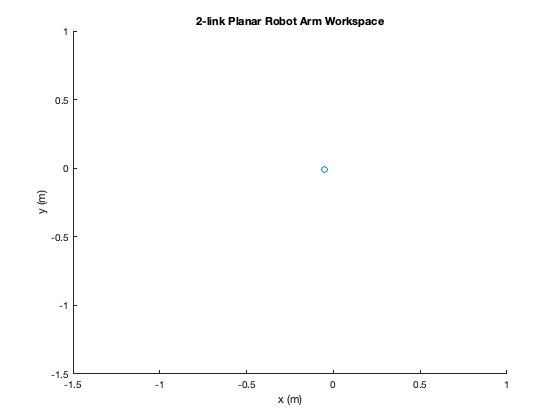

wspace = [];
for q1 = q1_range
    for q2 = q2_range
        % ADD THE SOLUTIONS FOR THE FORWARD KINEMATICS HERE
        %x = ???;
        %y = ???;
        wspace = [wspace;x,y];
    end
end
figure()
scatter(wspace(:,1),wspace(:,2))
title('2-link Planar Robot Arm Workspace')
xlabel('x (m)')
ylabel('y (m)')

**Question**: *How is the 2.12 robot's workspace limited? Are there certain regions that it will have difficulty reaching? Can you think of any reasons why this might be the case?*

**Question: ***Modify the code such that each joint is able to reach a range of angles form *$0^\circ$ to $360^\circ$. *Experiment with the following cases: the robot links are of equal length, link 1 is longer than link 2, link 1 is shorter than link 2. How does this affect the reachable workspace?*